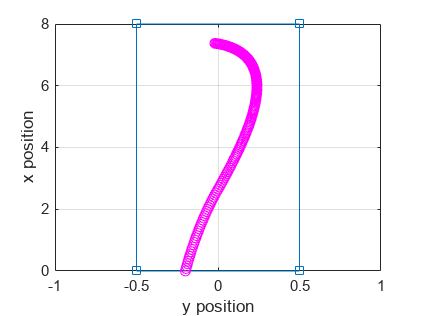

clear
clc
tspan = [0 10];
v0 = 1.6;
n = 200;
y0 = -0.2;
theta = 0.05;

[d1,d2] = drawField();
[y,vy,ty] = yEuler(@yOde,tspan,y0,v0,n,theta);
[x,vx,tx] = xEuler(@xOde,tspan,v0,n,theta);
[x1,vx1,y1,vy1] = calcStop(x,vx,y,vy,n+1);

% [y,vy,ty] = yEuler(@yOde,tspan,y0,1.3,n,theta);
% [x,vx,tx] = xEuler(@xOde,tspan,1.3,n,theta);
% [x2,vx2,y2,vy2] = calcStop(x,vx,y,vy,n+1,tspan);
% 
% [y,vy,ty] = yEuler(@yOde,tspan,y0,1.1,n,theta);
% [x,vx,tx] = xEuler(@xOde,tspan,1.1,n,theta);
% [x3,vx3,y3,vy3] = calcStop(x,vx,y,vy,n+1,tspan);

% plot(y,x,'o b',d1,d2,'s',y1,x1,'x r')

y0str = num2str(y0);
v0str = num2str(v0);
thetastr = num2str(theta);

s = strcat('y0 = ', y0str , ', v0 = ' , v0str , ', theta = ' , thetastr);

% plot(d1,d2,'s',y1,x1,'o m',y2,x2,'o c',y3,x3,'o y')
plot(d1,d2,'s -',y1,x1,'o m')
grid on
%title(s)
% title('Tre olika starthastigheter.')
ylabel('x position')
xlabel('y position')

hold off

animation(x1,y1)
diff = y(length(y))-y(1)

diff = 0.0349

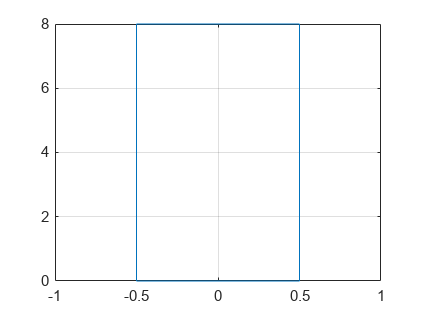


grid on

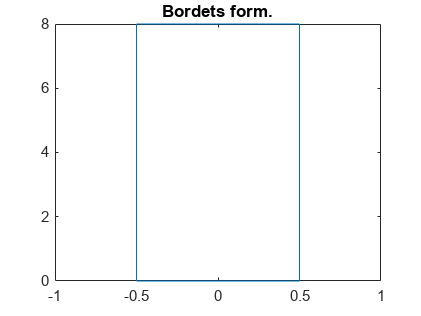

hold off
clear
clc
t = -0.5:0.01:0.5;
c1 = 1;

title("Bordets form.")

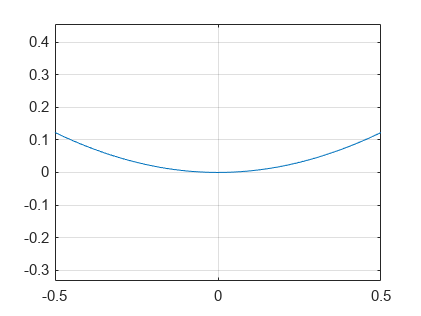

% plot(t,c1*exp(abs(t)))
plot(t,c1*-cos(t)+c1)
grid on
axis("equal")